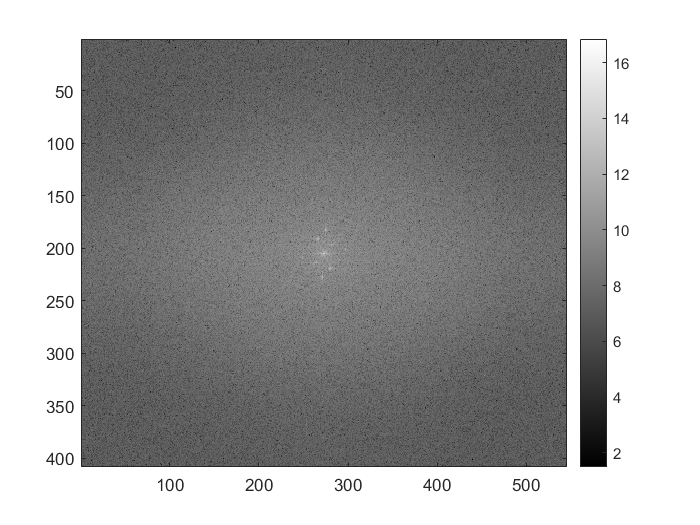


%Main script to read the image in and filter out the periodic signal from
%the image and then correct the non-uniform illumination 
clear; close all;

% fileName = input("Enter the name of the image with extention ex. Image.tif -> ", 's');
imOrig = (imread("Proj4.tif"));

[nx, ny] = size(imOrig);

FT = (fftshift(fft2((imOrig))));

%FT2 = fft2(double(imOrig));
%FT2 =  (1 + abs(fftshift(fft2((imOrig)))));

imagesc(log(1+abs(FT)))

colormap("gray");
colorbar()

%colormap("gray")
%k= [];
%m = 1;
ave = mean(mean(FT))

ave =            65.0000000000001 -  5.24106751881762e-15i

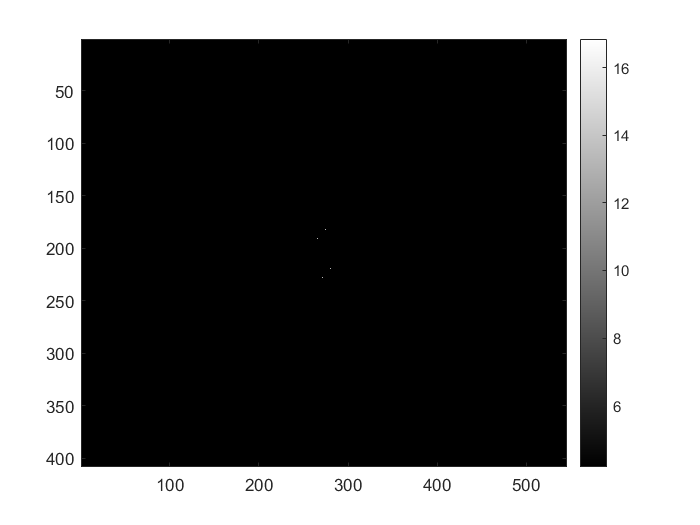

for i=1:size(FT,1)
    for j=1:size(FT,2)
        if abs(FT(i,j)) < 2E5 || (abs(FT(i,j)) > 1E6 && abs(FT(i,j)) < 2E7) ||...
                (abs(FT(i,j)) > 2E6 && abs(FT(i,j)) < 3E6) || (abs(FT(i,j)) > 2E5 && abs(FT(i,j)) < 2.5E5)
            FT(i,j) = ave;
        elseif abs(FT(i,j)) < 1E6            
            FT(i,j) = FT(i,j) * 2;
        end
    end
end
imagesc(log(1+abs(FT)))
colorbar()
colormap("gray")

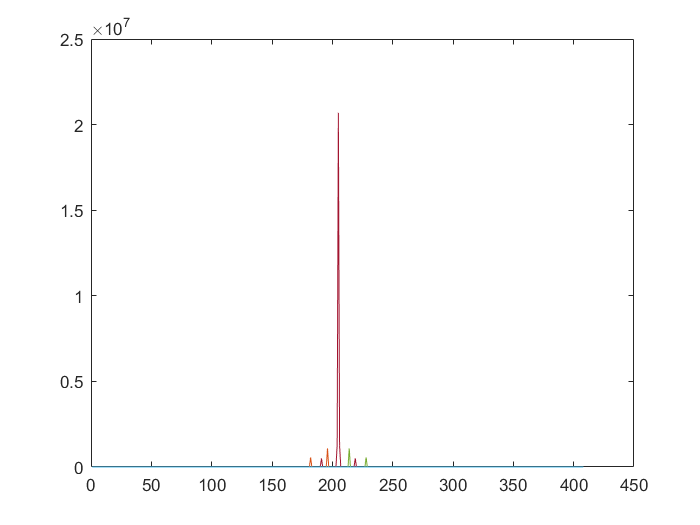

%imSharpen = highpass(FT2,0.5E7,2E7);
% imSharpenView = log(1 + abs(fftshift(imSharpen)));
% for i=1:m-1
%     FT2(k(1,1,i),k(1,2,i)) = 0;
% end
% figure; plot(log(abs(FT)));
% colorbar()
%colormap("gray")
plot(abs(FT))

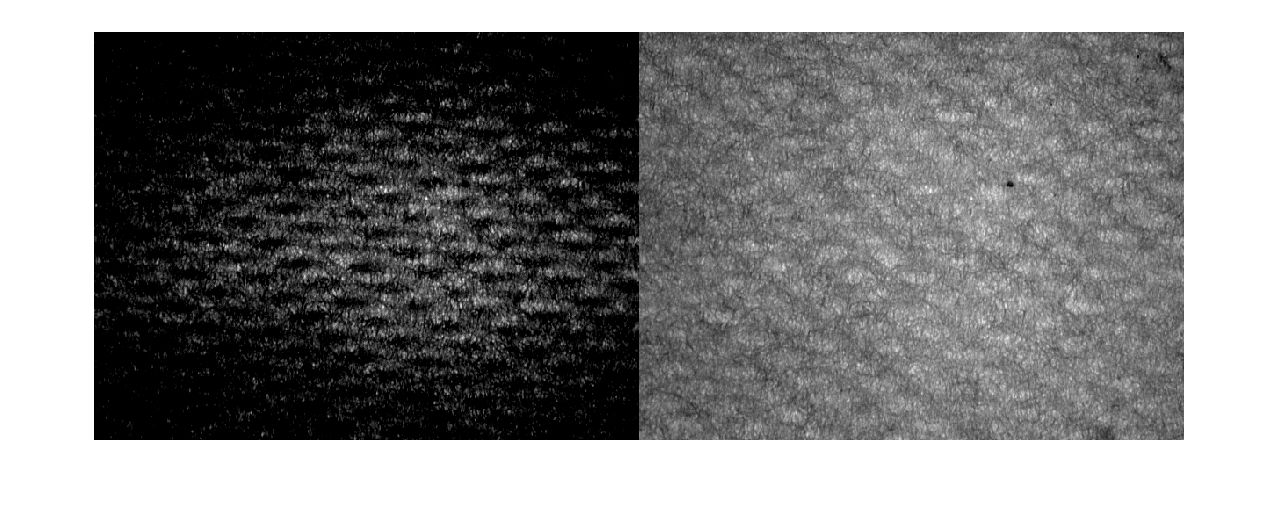

% 

 %g = real(ifft2(ifftshift((FT))));
 g = (fftshift(ifft2(FT)));
 figure;
 imshowpair((imOrig-uint8(abs(g))),imOrig,'montage');

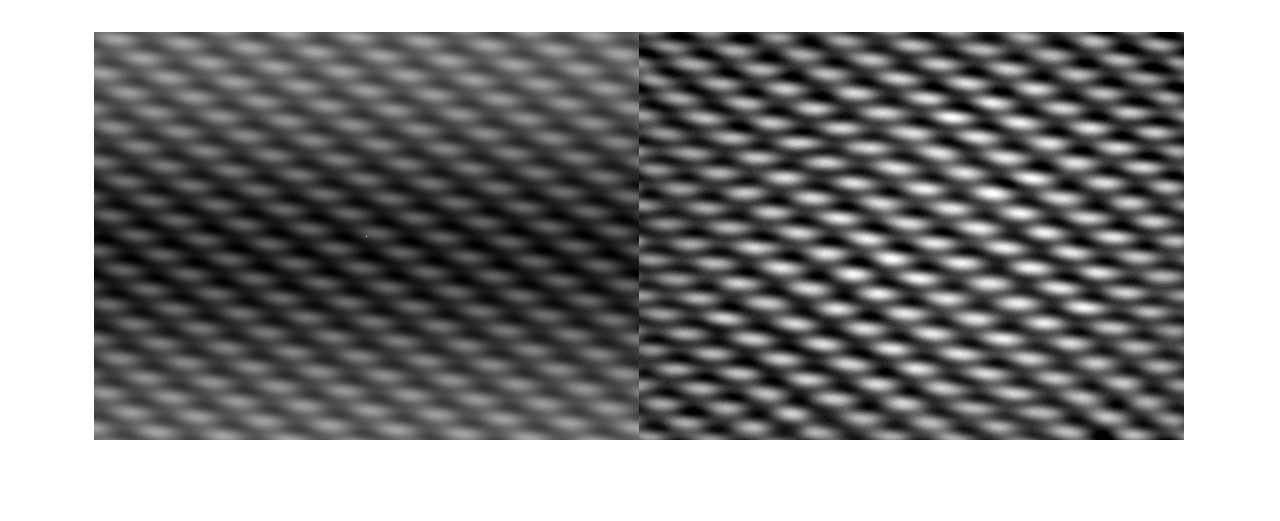

 imshowpair((uint8(abs(g))),imread("Proj4_pattern.tif"),'montage');

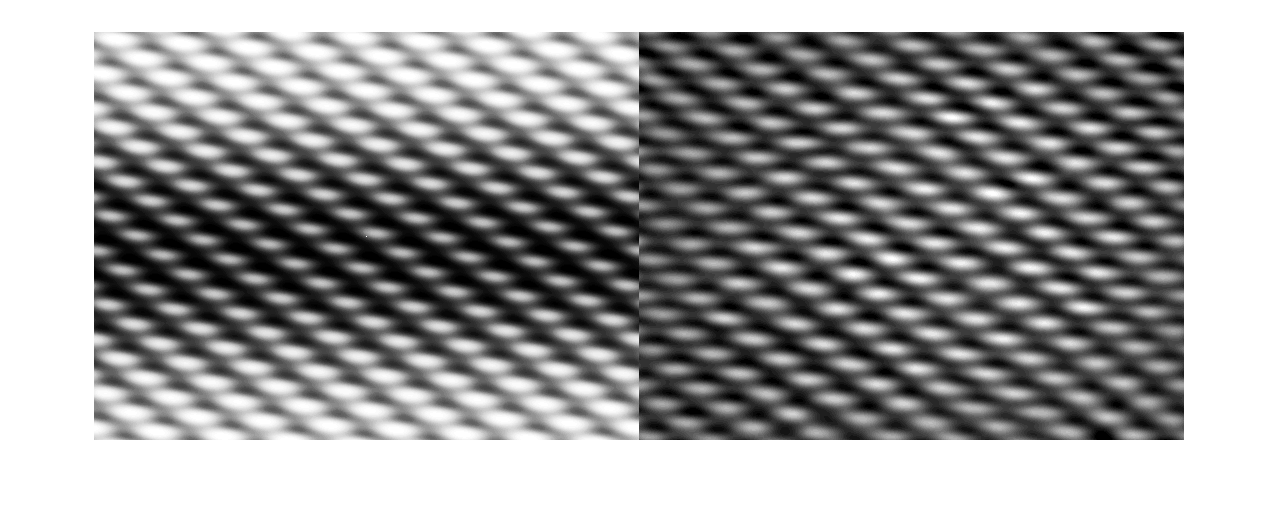

 imshowpair(histeq(uint8(abs(g))),imread("Proj4_pattern.tif"),'montage');